clearvars;
%inputs
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 3;
zmax = 8;
xint = 0.5;
yint = 0.5;
zint = 0.5;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
tenpererror = 1027;
fiftypererror = 204;
lsberr = 3581;
datasize = 4851;

mu_0 = 4*pi*10^-7; % T m/A^2
diameter = 5/16 * 2.54/100; %m
length = 1/8 *2.54/100; %m
Br = 14800/10000; %T
V = (diameter/2)^2*pi*length; %m^3
dipole_moment = Br * V / mu_0; %A m^2
M_0 = dipole_moment/V; %A/m
B_t = mu_0*V*M_0/(4*pi); %T m^3

lsb = 0.06493506494;

Reevaluate tenepererror and fifterpererror with regards to microT per LSB instead of relative error.

Confirm that B field formula works for location inputs

other: quantiify noise level

        show plots of B field 

        compare B field prediction to measured B field

        plot both on one plane

use current data estimate B field strength instead of manufacturer page.

lsberror = {};
z = zmin;
datamode = [];
sensor = [0, 0, -1];
locpred = [];
loc = [];
Bpred = [];

% for k = 1:ztotal
%     zstr = sprintf('%.1f', z);
%     y = ymin;
% 
%     for j = 1:ytotal
%         ystr = sprintf('%.1f', y);
%         x = xmin;
% 
%         for i = 1:xtotal         
%             xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Desktop\Watanabe_Project\02_16_2023_test\',xstr,'_',ystr,'_',zstr,'.data');
%             test = importdata(filename);
%             
%             b_x = test.data(:, 2);
%             xmode1 = mode(b_x);
%             b_x(b_x==xmode1) = NaN;
%             xmode2 = mode(b_x);
%             xerr = abs(xmode2-xmode1);
% 
%             b_y = test.data(:, 3);
%             ymode1 = mode(b_y);
%             b_y(b_y==ymode1) = NaN;
%             ymode2 = mode(b_y);
%             yerr = abs(ymode2-ymode1);
% 
%             b_z = test.data(:, 4);
%             zmode1 = mode(b_z);
%             b_z(b_z==zmode1) = NaN;
%             zmode2 = mode(b_z);
%             zerr = abs(zmode2-zmode1);
%             datamode = [datamode; [xmode1 ymode1 zmode1]];
%             loc = [loc; [x y z]];
%             
% 
%             syms a b c;
%             eqns = [3*(-1-c)*(-a)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 == xmode1, ...
%                 3*(-1-c)*(-b)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 == ymode1, ...
%                 3*(-1-c)*(-1-c)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 - 1/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^3 == zmode1];
%             S = solve(eqns, 'Real', true);
%             xmat = vpa(S.a);
%             ymat = vpa(S.b);         
%             zmat = vpa(S.c);
%             locmat = [xmat ymat zmat]
%             mask = any(imag(locmat),2);
%             locmat(mask,:)=[];
%             locmat = [xmat ymat zmat];
%             if size(locmat, 1) > 1
%                 locpred = [locpred; mean(locmat)];
%             else
%                 locpred = [locpred; locmat];
%             end
%             
%             magnet = [x y z];
%             R = norm(magnet - sensor);
%             Bx = B_t*3*(magnet(3)-sensor(3))*(magnet(1)-sensor(1))/R^5;
%             By = B_t*3*(magnet(3)-sensor(3))*(magnet(2)-sensor(2))/R^5;
%             Bz = B_t*3*(magnet(3)-sensor(3))*(magnet(3)-sensor(3))/R^5 + 1/R^3;
%             Bpred = [Bpred; [Bx, By, Bz]];
% 
%             x = x + xint;
%             if isnan(xerr) && isnan(yerr) && isnan(zerr)
%                 x = x + xint;
%             elseif xerr > 0.06493506494
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror, loc];
%                 x = x + xint;
%             elseif yerr > 0.06493506494
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror, loc];
%                 x = x + xint;
%             elseif zerr > 0.06493506494
%                 loc = append(xstr,'_',ystr,'_',zstr);
%                 lsberror = [lsberror, loc];
%                 x = x + xint;
%             else
%                 x = x + xint;
%             end
%         end
%         y = y + yint;
%     end
%     z = z + zint
% end

Bpred = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\02_16_2023_test\Bpred.txt');

loc = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\02_16_2023_test\location.txt'); %mm
datamode = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\02_16_2023_test\DataMode.txt'); %mT
davg = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\02_16_2023_test\DataAvg.txt'); %mT
davg.data;
davg1 = davg.data(:,2:7);
davg2 = sortrows(davg1, [3 2 1]);
dataavg = davg2(:, 4:6);

mu_0 = 4*pi*10^-7; % T m/A^2
diameter = 5/16 * 2.54/100; %m
length = 1/8 *2.54/100; %m
Br = 14800/10000; %T
V = (diameter/2)^2*pi*length; %m^3
dipole_moment = Br * V / mu_0; %A m^2
M_0 = dipole_moment/V; %A/m
B_t = mu_0*V*M_0/(4*pi); %T m^3


test =    1.8503e-08



sensor = [0, 0, -1];
H_0 = repelem([0 0 1], [4851], [1]);
X = sensor - loc;
R = sqrt(sum(X.^2, 2));
B = B_t*(3*dot(H_0, X, 2).*X./R.^5-H_0./R.^3)*10^12; %mT
datamode;
dataavg;

mode_err = abs((datamode - B)./B);
avg_err = abs((dataavg - B)./B);

% locpred = [];
% for ii = 1:size(B)
%     syms a b c;
%     eqns = [B_t*(3*(-1-c)*(-a)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5)*10^12 == datamode(ii, 1) ...
%             B_t*(3*(-1-c)*(-b)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5)*10^12 == datamode(ii, 2) ...
%             B_t*(3*(-1-c)*(-1-c)/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^5 - 1/sqrt((-a)^2 + (-b)^2 + (-1-c)^2)^3)*10^12 == datamode(ii, 3)];
% %     S = solve(eqns, 'Real', true);
%     S = vpasolve(eqns, [a b c]);
%     xmat = vpa(S.a);
%     ymat = vpa(S.b);         
%     zmat = vpa(S.c);
%     locmat = [xmat ymat zmat];
%     if size(locmat, 1) > 1
%         locpred = [locpred; mean(xmat) mean(ymat) mean(zmat)];
%     else
%         locpred = [locpred; xmat ymat zmat];
%     end
% end

locpred = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\02_16_2023_test\locpred.txt')

locpred =       -3.6691      -6.2374       5.3348
      -3.6691      -6.2374       5.3348
      -3.4066      -6.1318       5.3994
      -3.2356      -6.1477       5.2734
      -2.7802      -6.1782       5.3783
      -2.6458      -6.1734        5.253
      -2.2387      -6.1564       5.3287
      -1.6152      -6.1917       5.4196
      -1.2983       -6.232       5.3213
     -0.77482      -6.1986       5.4921



location_err = (locpred - loc)./loc

location_err =      -0.26619      0.24748      0.77826
     -0.18465      0.24748      0.77826
     -0.14836      0.22636      0.79978
    -0.075539      0.22953      0.75779
    -0.073276      0.23563      0.79275
     0.058304      0.23469      0.75099
      0.11935      0.23129      0.77623
     0.076819      0.23834      0.80654
      0.29833       0.2464      0.77377
      0.54965      0.23972      0.83071


maxmode_xerr = max(locpred(:,1))

maxmode_xerr =        4.0488


maxmode_yerr = max(locpred(:,2))

maxmode_yerr =        3.7162


maxmode_zerr = max(locpred(:,3))

maxmode_zerr =        11.163



locpred_dataavg = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\02_16_2023_test\locpred_dataavg.txt')

locpred_dataavg =       -3.6611      -6.2384       5.3297
      -3.6233       -6.243       5.3056
      -3.4152      -6.1473       5.3772
      -3.2112      -6.1686       5.2867
      -2.7802      -6.1782       5.3783
      -2.6389      -6.1712       5.2603
      -2.2387      -6.1564       5.3287
      -1.6698      -6.1746        5.412
      -1.2902      -6.1928       5.3615
     -0.76691      -6.1943       5.4722



locdiff = locpred - loc

locdiff =        1.3309      -1.2374       2.3348
      0.83094      -1.2374       2.3348
      0.59344      -1.1318       2.3994
      0.26439      -1.1477       2.2734
      0.21983      -1.1782       2.3783
     -0.14576      -1.1734        2.253
      -0.2387      -1.1564       2.3287
     -0.11523      -1.1917       2.4196
     -0.29833       -1.232       2.3213
     -0.27482      -1.1986       2.4921


maxmode_xdiff = max(locdiff(:,1))

maxmode_xdiff =        1.6063


maxmode_ydiff = max(locdiff(:,2))

maxmode_ydiff =       -1.1157


maxmode_zdiff = max(locdiff(:,3))

maxmode_zdiff =        3.3189



dataavg_loc_err = (locpred_dataavg - loc)./loc

dataavg_loc_err =      -0.26779      0.24769      0.77655
     -0.19481       0.2486      0.76852
     -0.14621      0.22946       0.7924
    -0.082514      0.23373      0.76222
    -0.073276      0.23563      0.79275
     0.055561      0.23423      0.75342
      0.11935      0.23129      0.77623
      0.11322      0.23492        0.804
      0.29016      0.23855      0.78715
      0.53382      0.23885      0.82407


maxavg_xerr = max(locpred_dataavg(:,1))

maxavg_xerr =          3.99


maxavg_yerr = max(locpred_dataavg(:,2))

maxavg_yerr =         3.677


maxavg_zerr = max(locpred_dataavg(:,3))

maxavg_zerr =        11.163



avgdiff = locpred_dataavg - loc

avgdiff =        1.3389      -1.2384       2.3297
      0.87667       -1.243       2.3056
      0.58483      -1.1473       2.3772
       0.2888      -1.1686       2.2867
      0.21983      -1.1782       2.3783
      -0.1389      -1.1712       2.2603
      -0.2387      -1.1564       2.3287
     -0.16983      -1.1746        2.412
     -0.29016      -1.1928       2.3615
     -0.26691      -1.1943       2.4722


maxavg_xdiff = max(avgdiff(:,1))

maxavg_xdiff =        1.5721


maxavg_ydiff = max(avgdiff(:,2))

maxavg_ydiff =        -1.143


maxavg_zdiff = max(avgdiff(:,3))

maxavg_zdiff =        3.3189


B_thao = readtable('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\Bfield_0226.csv');
B_sim = [B_thao.Var1*1000 B_thao.Var2*1000 B_thao.Var3*1000-1 B_thao.Var4*1000 B_thao.Var5*1000 B_thao.Var6*1000]

B_sim =            -5           -5            3        -21.8        -21.8        -9.64
           -5           -5            4        -16.7        -16.7        -5.22
           -5           -5            5        -12.6        -12.6        -2.81
           -5           -5            6         -9.4         -9.4        -1.51
           -5           -5            7        -6.99        -6.99       -0.812
           -5           -5            8         -5.2         -5.2       -0.433
           -5           -4            3          -29        -23.6        -3.35
           -5           -4            4        -21.3        -17.5       -0.185
           -5           -4            5        -15.5        -12.8         1.04
           -5           -4            6        -11.2        -9.38         1.36


datamode

datamode =        -15.68      -26.656        6.272
       -15.68      -26.656        6.272
       -15.68      -28.224         7.84
       -15.68      -29.792         7.84
      -14.112       -31.36        9.408
      -14.112      -32.928        9.408
      -12.544      -34.496       10.976
       -9.408      -36.064       12.544
        -7.84      -37.632       12.544
       -4.704      -37.632       14.112


dataavg

dataavg =        -15.68      -26.719        6.272
       -15.68      -27.017        6.272
       -15.68      -28.224       7.6518
      -15.476      -29.729         7.84
      -14.112       -31.36        9.408
      -14.081      -32.928       9.4707
      -12.544      -34.496       10.976
       -9.753      -36.064       12.544
        -7.84      -37.632        13.03
      -4.6883      -37.867       14.112


B = [loc, B]

B =            -5           -5            3      -31.372      -31.372      -9.4116
         -4.5           -5            3      -34.032      -37.813      -8.3503
           -4           -5            3      -36.208       -45.26       -6.789
         -3.5           -5            3      -37.558      -53.654      -4.6948
           -3           -5            3      -37.682      -62.803      -2.0934
         -2.5           -5            3      -36.172      -72.344      0.90429
           -2           -5            3      -32.691      -81.728       4.0864
         -1.5           -5            3      -27.074      -90.248       7.1447
           -1           -5            3      -19.423      -97.114       9.7114
         -0.5           -5            3      -10.159      -101.59       11.429


B = sortrows(B, [1 2])

B =            -5           -5            3      -31.372      -31.372      -9.4116
           -5           -5          3.5      -30.195      -30.195      -4.2497
           -5           -5            4      -28.488      -28.488  -4.0123e-15
           -5           -5          4.5       -26.46       -26.46       3.3677
           -5           -5            5       -24.28       -24.28       5.9351
           -5           -5          5.5      -22.072      -22.072       7.8101
           -5           -5            6      -19.923      -19.923       9.1076
           -5           -5          6.5      -17.889      -17.889       9.9383
           -5           -5            7      -16.002      -16.002       10.401
           -5           -5          7.5      -14.277      -14.277       10.582


loc;
modeplot = [loc, datamode];
modeplot = sortrows(modeplot, [1 2])

modeplot =            -5           -5            3       -15.68      -26.656        6.272
           -5           -5          3.5      -14.112      -25.088         7.84
           -5           -5            4      -12.544      -21.952         7.84
           -5           -5          4.5      -10.976      -18.816        9.408
           -5           -5            5      -10.976      -17.248        9.408
           -5           -5          5.5       -9.408       -15.68        9.408
           -5           -5            6        -7.84      -14.112        9.408
           -5           -5          6.5        -7.84      -12.544         7.84
           -5           -5            7       -6.272      -10.976         7.84
           -5           -5          7.5       -6.272       -9.408         7.84


B_t

B_t =    1.8503e-08


% test = Br*V/(4*pi);
X = sensor - modeplot(:,1:3)

X =             5            5           -4
            5            5         -4.5
            5            5           -5
            5            5         -5.5
            5            5           -6
            5            5         -6.5
            5            5           -7
            5            5         -7.5
            5            5           -8
            5            5         -8.5


R = sqrt(sum(X.^2, 2))

R =         8.124
       8.3815
       8.6603
       8.9582
       9.2736
       9.6047
       9.9499
       10.308
       10.677
       11.057


B_not = (3*dot(H_0, X, 2).*X./R.^5-H_0./R.^3)*10^12;
xfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-x(:,1))./R.^5)*10^12;
beta0 = [10^-12];
mdlx = fitnlm(modeplot(:,1:3), modeplot(:,4), xfieldfun, beta0)

mdlx = Nonlinear regression model:
    y ~ F(b,x)

Estimated Coefficients:
          Estimate       SE        tStat     pValue
          ________    _________    ______    ______

    b1    0.35608     0.0030406    117.11      0   


Number of observations: 4851, Error degrees of freedom: 4850
Root Mean Squared Error: 7.87
R-Squared: 0.728,  Adjusted R-Squared 0.728
F-statistic vs. zero model: 1.37e+04, p-value = 0

yfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-x(:,2))./R.^5)*10^12;
mdly = fitnlm(modeplot(:,1:3), modeplot(:,5), yfieldfun, beta0)

mdly = Nonlinear regression model:
    y ~ F(b,x)

Estimated Coefficients:
          Estimate       SE       tStat     pValue
          ________    ________    ______    ______

    b1     0.3876     0.004197    92.351      0   


Number of observations: 4851, Error degrees of freedom: 4850
Root Mean Squared Error: 10.9
R-Squared: 0.584,  Adjusted R-Squared 0.584
F-statistic vs. zero model: 8.53e+03, p-value = 0

zfieldfun = @(b, x)(b*V/(4*pi))*(3*(-1-x(:,3)).*(-1-x(:,3))./R.^5-1./R.^3)*10^12;
mdlz = fitnlm(modeplot(:,1:3), modeplot(:,6), zfieldfun, beta0)

mdlz = Nonlinear regression model:
    y ~ F(b,x)

Estimated Coefficients:
          Estimate       SE        tStat     pValue
          ________    _________    ______    ______

    b1    0.49621     0.0047596    104.25      0   


Number of observations: 4851, Error degrees of freedom: 4850
Root Mean Squared Error: 19.5
R-Squared: -0.303,  Adjusted R-Squared -0.303
F-statistic vs. zero model: 1.09e+04, p-value = 0


bx = table2array(mdlx.Coefficients)

bx =       0.35608    0.0030406       117.11            0


by = table2array(mdly.Coefficients)

by =        0.3876     0.004197       92.351            0


bz = table2array(mdlz.Coefficients)

bz =       0.49621    0.0047596       104.25            0


B_tguess = (bx(1)+by(1)+bz(1))/3

B_tguess =        0.4133


B_guess = B_tguess.*V/(4*pi)*B_not

B_guess =       -8.7608      -8.7608      -2.6282
      -8.4322      -8.4322      -1.1868
      -7.9554      -7.9554  -1.1205e-15
      -7.3892      -7.3892      0.94044
      -6.7803      -6.7803       1.6574
      -6.1637      -6.1637        2.181
      -5.5636      -5.5636       2.5434
      -4.9956      -4.9956       2.7753
      -4.4686      -4.4686       2.9046
       -3.987       -3.987        2.955


B_guess = [modeplot(:, 1:3) B_guess];

B_guess =            -5           -5            3      -8.7608      -8.7608      -2.6282
           -5           -5          3.5      -8.4322      -8.4322      -1.1868
           -5           -5            4      -7.9554      -7.9554  -1.1205e-15
           -5           -5          4.5      -7.3892      -7.3892      0.94044
           -5           -5            5      -6.7803      -6.7803       1.6574
           -5           -5          5.5      -6.1637      -6.1637        2.181
           -5           -5            6      -5.5636      -5.5636       2.5434
           -5           -5          6.5      -4.9956      -4.9956       2.7753
           -5           -5            7      -4.4686      -4.4686       2.9046
           -5           -5          7.5       -3.987       -3.987        2.955


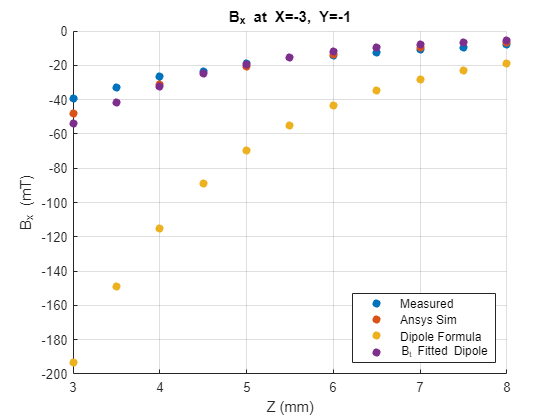

scatter(modeplot(1013:1023, 3), modeplot(1013:1023, 4), "filled")
hold on;
scatter(B_sim(157:162, 3), B_sim(157:162, 4), 'filled')
scatter(B(1013:1023, 3), B(1013:1023, 4), "filled")
scatter(B_guess(1013:1023, 3), B_guess(1013:1023, 4), "filled")
grid on;
title("B_x at X=-3, Y=-1")
xlabel("Z (mm)")
ylabel("B_x (mT)")
legend('Measured', 'Ansys Sim', 'Dipole Formula', 'B_t Fitted Dipole', 'Location', 'southeast')
hold off;

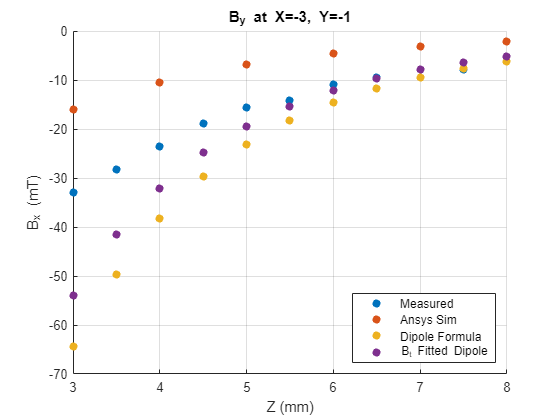


scatter(modeplot(1013:1023, 3), modeplot(1013:1023, 5), "filled")
hold on;
scatter(B_sim(157:162, 3), B_sim(157:162, 5), 'filled')
scatter(B(1013:1023, 3), B(1013:1023, 5), "filled")
scatter(B_guess(1013:1023, 3), B_guess(1013:1023, 4), "filled")
grid on;
title("B_y at X=-3, Y=-1")
xlabel("Z (mm)")
ylabel("B_x (mT)")
legend('Measured', 'Ansys Sim', 'Dipole Formula', 'B_t Fitted Dipole', 'Location', 'southeast')
hold off;

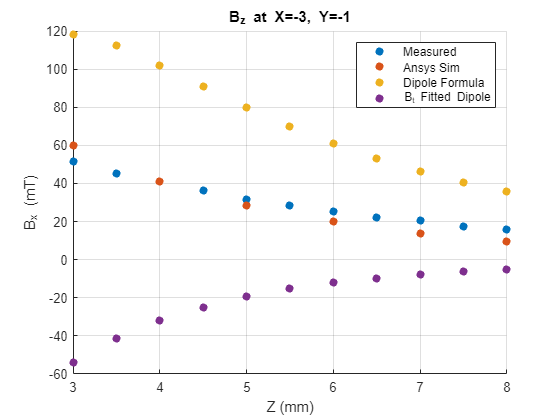


scatter(modeplot(1013:1023, 3), modeplot(1013:1023, 6), "filled")
hold on;
scatter(B_sim(157:162, 3), B_sim(157:162, 6), 'filled')
scatter(B(1013:1023, 3), B(1013:1023, 6), "filled")
scatter(B_guess(1013:1023, 3), B_guess(1013:1023, 4), "filled")
grid on;
title("B_z at X=-3, Y=-1")
xlabel("Z (mm)")
ylabel("B_x (mT)")
legend('Measured', 'Ansys Sim', 'Dipole Formula', 'B_t Fitted Dipole')
hold off;

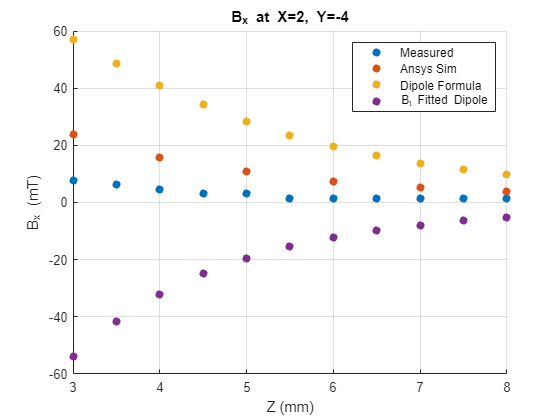

scatter(modeplot(3257:3267, 3), modeplot(3257:3267, 4), "filled")
hold on;
scatter(B_sim(469:474, 3), B_sim(469:474, 4), 'filled')
scatter(B(3257:3267, 3), B(3257:3267, 4), "filled")
scatter(B_guess(1013:1023, 3), B_guess(1013:1023, 4), "filled")
grid on;
title("B_x at X=2, Y=-4")
xlabel("Z (mm)")
ylabel("B_x (mT)")
legend('Measured', 'Ansys Sim', 'Dipole Formula', 'B_t Fitted Dipole', 'Location', 'northeast')
hold off;

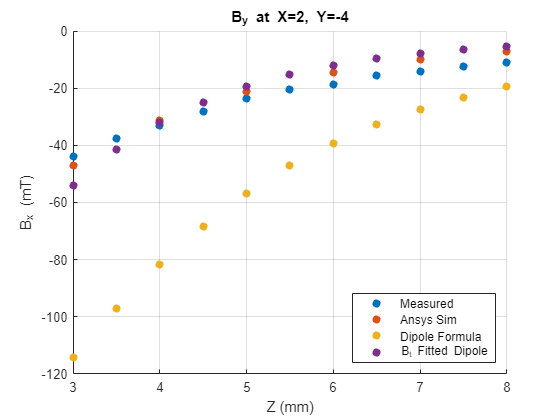


scatter(modeplot(3257:3267, 3), modeplot(3257:3267, 5), "filled")
hold on;
scatter(B_sim(469:474, 3), B_sim(469:474, 5), 'filled')
scatter(B(3257:3267, 3), B(3257:3267, 5), "filled")
scatter(B_guess(1013:1023, 3), B_guess(1013:1023, 4), "filled")
grid on;
title("B_y at X=2, Y=-4")
xlabel("Z (mm)")
ylabel("B_x (mT)")
legend('Measured', 'Ansys Sim', 'Dipole Formula', 'B_t Fitted Dipole', 'Location', 'southeast')
hold off;

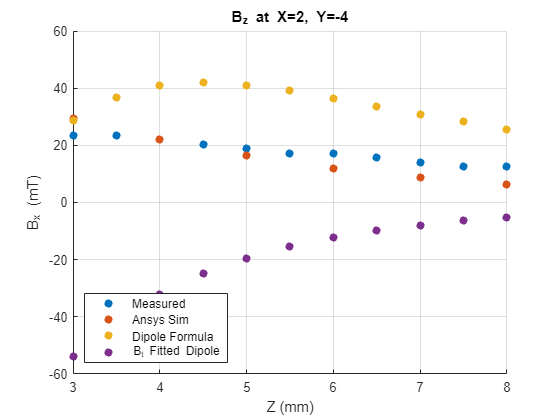


scatter(modeplot(3257:3267, 3), modeplot(3257:3267, 6), "filled")
hold on;
scatter(B_sim(469:474, 3), B_sim(469:474, 6), 'filled')
scatter(B(3257:3267, 3), B(3257:3267, 6), "filled")
scatter(B_guess(1013:1023, 3), B_guess(1013:1023, 4), "filled")
grid on;
title("B_z at X=2, Y=-4")
xlabel("Z (mm)")
ylabel("B_x (mT)")
legend('Measured', 'Ansys Sim', 'Dipole Formula', 'B_t Fitted Dipole', 'Location', 'southwest')
hold off;